# IQ Demodulator E Function

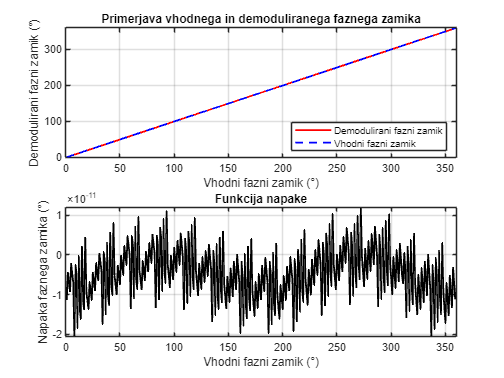

clc
clear all
close all

% Parameteri
FREQUENCY = 10e6;           % Signal frequency
SAMPLE_RATE = 62.5e6;       % Sampling rate
SAMPLE_COUNT = 4096;        % Number of samples
WINDOW_SIZE = 100;          % Lowpass filter window size
PHASE_SHIFT_DEG = 0:1:359;  % Range of phase shifts in degrees

% Izpeljani parametri
t = (0:SAMPLE_COUNT-1) / SAMPLE_RATE;
PHASE_SHIFT = deg2rad(PHASE_SHIFT_DEG);
num_shifts = length(PHASE_SHIFT);

% Referenčna signala
lo = sin(2*pi*FREQUENCY*t);          % Osnovni
lo90 = sin(2*pi*FREQUENCY*t - pi/2); % V kvadraturi

% Inicializacija rezultatov
demodulated_phases = zeros(1, num_shifts); % To store demodulated phases
phase_errors = zeros(1, num_shifts);       % To store phase errors

% Iteriraj čez vse faze
for idx = 1:num_shifts
    % Generacija vhodnega signala
    in_test = sin(2*pi*FREQUENCY*t - PHASE_SHIFT(idx));
    
    % Demodulacija v obliki korelacije
    I_hf = in_test .* lo;
    Q_hf = in_test .* lo90;
    
    % Nizkoprepustni filter
    b = (1/WINDOW_SIZE) * ones(1, WINDOW_SIZE);
    a = 1;
    I_filtered = filter(b, a, I_hf);
    Q_filtered = filter(b, a, Q_hf);
    
    % Zadnja točka ustaljenega stanja
    final_I = I_filtered(end);
    final_Q = Q_filtered(end);
    
    % Izračun faze
     demodulated_phases(idx) = mod(atan2d(final_Q, final_I), 360);
    % Izračun napake faze
     phase_errors(idx) = demodulated_phases(idx) - PHASE_SHIFT_DEG(idx);
end

% Izris rezultatov
figure;

subplot(2, 1, 1);
plot(PHASE_SHIFT_DEG(2:end), demodulated_phases(2:end), 'r', 'LineWidth', 1.5);
hold on;
plot(PHASE_SHIFT_DEG(2:end), PHASE_SHIFT_DEG(2:end), 'b--', 'LineWidth', 1.5);
title('Primerjava vhodnega in demoduliranega faznega zamika');
xlabel('Vhodni fazni zamik (°)');
ylabel('Demodulirani fazni zamik (°)');
legend({'Demodulirani fazni zamik', 'Vhodni fazni zamik'}, 'Location', 'southeast');
ylim([0 360])
xlim([0 360])
grid on;

subplot(2, 1, 2);
plot(PHASE_SHIFT_DEG(2:end), phase_errors(2:end), 'k', 'LineWidth', 1.5);
title('Funkcija napake');
xlabel('Vhodni fazni zamik (°)');
ylabel('Napaka faznega zamika (°)');
xlim([0 360])
grid on;


% Izpis napak
fprintf('Največja napaka faze: %.2f degrees\n', max(abs(phase_errors(2:end))));

Največja napaka faze: 0.00 degrees


fprintf('Povprečna absolutna napaka faze: %.2f degrees\n', mean(abs(phase_errors(2:end))));

Povprečna absolutna napaka faze: 0.00 degrees
